Name: Yusu (Cosmo) Zhao

Student Number: 20761282

% Initialize your variables such as amplitude and frequency
A = 3; % Amplitude
f = 2; % Frequency, in Hertz

T = 6; % Total time, in seconds
sf = 20; % Sampling frequency, in Hertz
ts = 1/sf; % Time step (inverse of sampling frequency)
t = 0:ts:T; % Time vector (a vector containing 0, ts, 2ts, 3ts, ... T)

% Generate the sin wave. The wave MUST be stored in the variable x.
x = A * sin(2*pi*f*t)

x =          0    1.7634    2.8532    2.8532    1.7634    0.0000   -1.7634   -2.8532   -2.8532   -1.7634   -0.0000    1.7634    2.8532    2.8532    1.7634    0.0000   -1.7634   -2.8532   -2.8532   -1.7634   -0.0000    1.7634    2.8532    2.8532    1.7634    0.0000   -1.7634   -2.8532   -2.8532   -1.7634   -0.0000    1.7634    2.8532    2.8532    1.7634    0.0000   -1.7634   -2.8532   -2.8532   -1.7634   -0.0000    1.7634    2.8532    2.8532    1.7634    0.0000   -1.7634   -2.8532   -2.8532   -1.7634


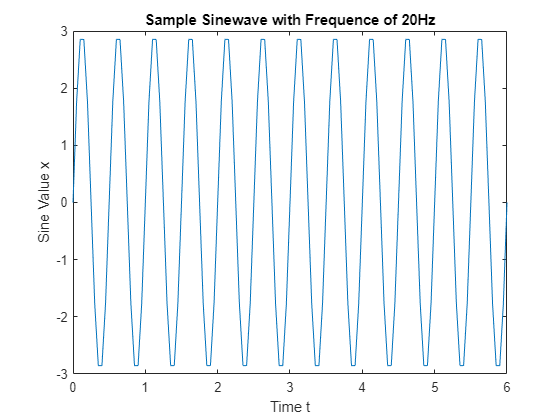

plot(t, x)
title('Sample Sinewave with Frequence of 20Hz')
xlabel('Time t')
ylabel('Sine Value x')

% Change sampling frequency to 5 Hz and make a new graph
sf = 5; % Sampling frequency, in Hertz
ts = 1/sf; % Time step (inverse of sampling frequency)
t = 0:ts:T; % Time vector (a vector containing 0, ts, 2ts, 3ts, ... T)

% Generate the sin wave. The wave MUST be stored in the variable x2.
x2 = A * sin(2*pi*f*t)

x2 =          0    1.7634   -2.8532    2.8532   -1.7634   -0.0000    1.7634   -2.8532    2.8532   -1.7634   -0.0000    1.7634   -2.8532    2.8532   -1.7634   -0.0000    1.7634   -2.8532    2.8532   -1.7634   -0.0000    1.7634   -2.8532    2.8532   -1.7634   -0.0000    1.7634   -2.8532    2.8532   -1.7634   -0.0000


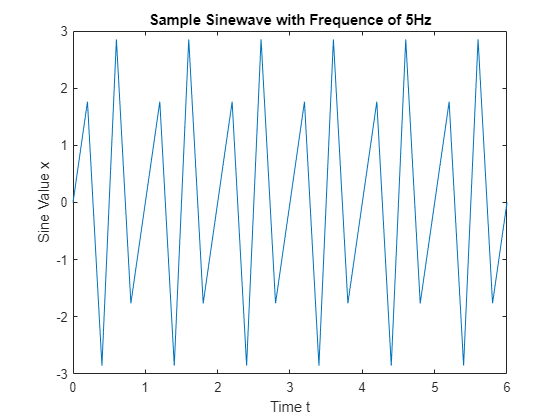

plot(t, x2)
title('Sample Sinewave with Frequence of 5Hz')
xlabel('Time t')
ylabel('Sine Value x')

As we decrese the sampling frequency from 20Hz to 5Hz, we sample fewer points and the plot becomes less smooth. This is because our time step ts = 1/sf is increased from 1/20 to 1/5. This means our new steps is four times wider than the original one. Wider steps also means that we are more likely to miss the peak or bottom, and that explains why the second graph does not seem to have a universal amplitude. 

When we are sampling points by a frequency and draw the sampled points as a plot, the matlab will simply connect those sample points with straight linear lines. The result diagram is just a estimation. If we increase the frequency, which essentially means we sample more points, the linear approximation we get will become more accurate, and the diagram we get will become closer to the original one.